% ACF of unbiased, 1000 sample white gaussian noise

x = randn(1000,1);
[r,lags]= xcorr(x,'unbiased');
figure(1);
ACF_plot = plot(lags,r);
set(ACF_plot, 'Marker', 'none')
title('Unbiased estimate of ACF for 1000 WGN samples')
ylabel('Correlation')
xlabel('τ (Correlation lag)')
axis([-999 999 -0.8 1.2])


% using zoom function to focus onto the region |τ | < 50

figure(2);
ACF_plot = plot(lags,r);
set(ACF_plot, 'Marker', 'none')
title('Unbiased estimate of ACF for 1000 WGN samples')
ylabel('Correlation')
xlabel('τ (Correlation lag)')
% Zoom in on the x-axis
zoom on;
axis([-50, 50, ylim]);
zoom off;

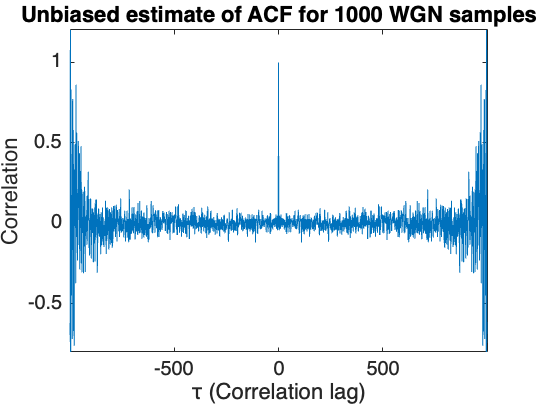

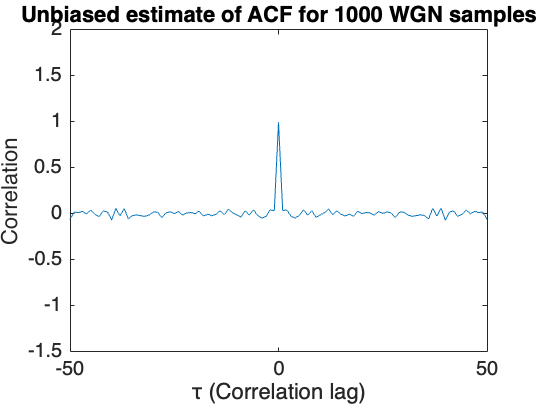

% Generate a 1000-sample WGN vector x and filter it by a moving average (MA) filter with unit coefficients of [10]
% of order 9 and plot the acf

clear all;
x = randn(1000,1);
y=filter(ones(9,1),[1],x);
[r,lags]= xcorr(y,'unbiased');
figure(3);
ACF = stem(lags,r);
title('ACF estimate for 9th order MA filter applied on 1000 samples of WGN')
ylabel('Correlation')
xlabel('τ (Correlation lag)')
xlim([-20 20])


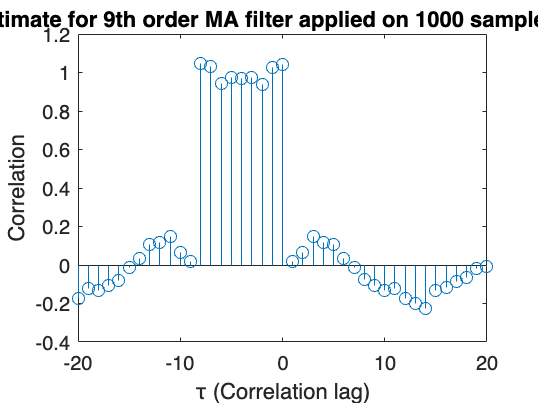

% Estimate the CCF for the sequences x and y generated above 

clear all;
x = randn(1000,1);
y=filter(ones(9,1),[1],x);
[r,lags]= xcorr(x,y,'unbiased');
figure(4);
ACF = stem(lags,r);
title('CCF estimate for 9th order MA filter applied on 1000 samples of WGN')
ylabel('Correlation')
xlabel('τ (Correlation lag)')
xlim([-20 20])

clear all;
figure(6);
hold on
xlim([-2.5 2.5])
ylim([-1.5 1.5])
xlabel('a_1')
ylabel('a_2')
title('Stability Triangle')

for i = 1:1000
    a1 = unifrnd(-2.5, 2.5);
    a2 = unifrnd(-1.5, 1.5);
    roots_func = roots([1, -a1,-a2]);
    
    % Generate AR(2) process with coefficients a1 and a2
    x = zeros(1000,1);
    x(1) = randn;
    x(2) = randn;
    for n = 3:1000
        x(n) = a1*x(n-1) + a2*x(n-2) + randn;
    end
    
    % Check for stable
    if all(abs(roots_func) < 1)
        plot(a1, a2, '*b')
    else
        plot(a1, a2, '*r')
    end
end


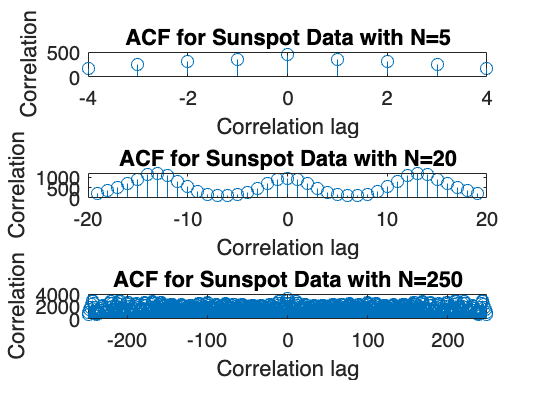

% 2.3.2

clear all;
data = load('sunspot.dat');
sunspot = data(:,2); %sunspot data from the second column

N = 5; % Data length
% Compute ACF of sunspot data up to lag N
[acf, lags] = xcorr(sunspot(1:N), 'unbiased');
figure(9);
% Plot ACF
subplot(3,1,1)
stem(lags, acf);
xlabel('Correlation lag');
ylabel('Correlation');
title('ACF for Sunspot Data with N=5');

N =20 ;
[acf, lags] = xcorr(sunspot(1:N), 'unbiased');
subplot(3,1,2)
stem(lags, acf);
xlabel('Correlation lag');
ylabel('Correlation');
title('ACF for Sunspot Data with N=20');

N =250 ;
[acf, lags] = xcorr(sunspot(1:N), 'unbiased');
subplot(3,1,3)
stem(lags, acf);
xlabel('Correlation lag');
ylabel('Correlation');
title('ACF for Sunspot Data with N=250');

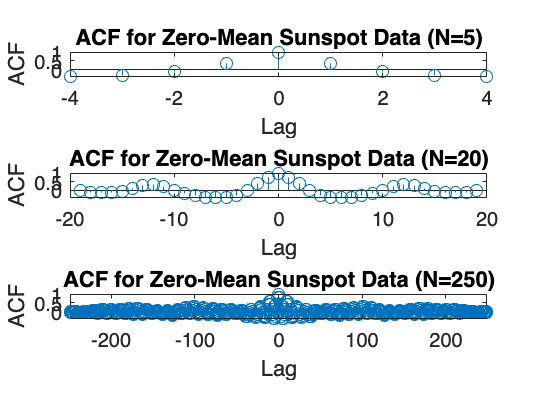

% 2.3.2 - normalised version for comparision 
clear all;
load sunspot.dat % Load sunspot data
sunspot_data = sunspot(:, 2); % Extract sunspot data from second column

N = 5; % Data length
sunspot_data = sunspot_data(1:N) - mean(sunspot_data(1:N)); % Zero-mean version of sunspot data up to N

% Compute ACF of zero-mean sunspot data up to lag N-1
[acf, lags] = xcorr(sunspot_data, N-1, 'coeff');

% Plot ACF
subplot(3,1,1)
stem(lags, acf);
xlabel('Lag');
ylabel('ACF');
title(sprintf('ACF for Zero-Mean Sunspot Data (N=%d)', N));

load sunspot.dat % Load sunspot data
sunspot_data = sunspot(:, 2); % Extract second column of data
N = 20; % Data length

% Compute zero-mean version of sunspot data
sunspot_zero_mean = sunspot_data(1:N) - mean(sunspot_data(1:N));

% Compute ACF of zero-mean sunspot data up to lag N
[acf, lags] = xcorr(sunspot_zero_mean(1:N), N-1, 'coeff');

% Plot ACF
subplot(3,1,2)
stem(lags, acf);
xlabel('Lag');
ylabel('ACF');
title(sprintf('ACF for Zero-Mean Sunspot Data (N=%d)', N));

load sunspot.dat % Load sunspot data
sunspot_data = sunspot(:, 2); % Extract second column of data
N = 250; % Data length

% Compute zero-mean version of sunspot data
sunspot_zero_mean = sunspot_data(1:N) - mean(sunspot_data(1:N));

% Compute ACF of zero-mean sunspot data up to lag N
[acf, lags] = xcorr(sunspot_zero_mean(1:N), N-1, 'coeff');

% Plot ACF
subplot(3,1,3)
stem(lags, acf);
xlabel('Lag');
ylabel('ACF');
title(sprintf('ACF for Zero-Mean Sunspot Data (N=%d)', N));

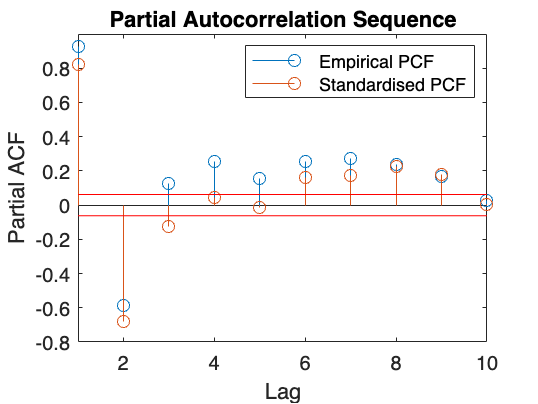

% 2.3.3
clear all;
load sunspot.dat; % Load sunspot data
x = sunspot(:,2); % Extract data from second column
[arcoefs,E,K] = aryule(x,15);
pacf = -K;
stem(pacf)
xlabel('Lag')
ylabel('Partial ACF')
title('Partial Autocorrelation Sequence')
xlim([1 10])
hold on
x_std = (x - mean(x)) / std(x);
[arcoefs,E,K] = aryule(x_std,15);
pacf = -K;
stem(pacf)
xlabel('Lag')
ylabel('Partial ACF')
title('Partial Autocorrelation Sequence')
conf = sqrt(2)*erfinv(0.95)/sqrt(1000);
plot(xlim,[1 1]'*[-conf conf],'r')
hold off
legend(["Empirical PCF","Standardised PCF"])

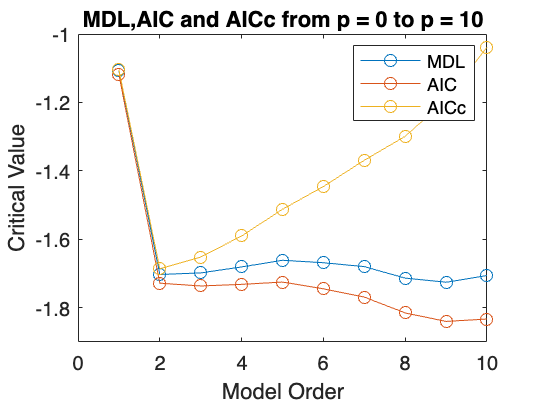

% 2.3.4

clear all;
load sunspot.dat; 
sunspot_data = sunspot(:,2); 

% Standardize the data to zero mean and unit variance
sunspot_std = (sunspot_data - mean(sunspot_data)) / std(sunspot_data);


max_p = 10; % Maximum model order
mdl = zeros(max_p, 1);
aic = zeros(max_p, 1);
aicc = zeros(max_p, 1);

for p = 1:max_p
    
    [a, e, k] = aryule(sunspot_std, p);
    

    n = length(sunspot_std);
    mdl(p) = log(e) + p*log(n)/n;
    aic(p) = log(e) + 2*p/n;
    aicc(p) = aic(p) + (2*p*(p+1))/(n-p-1);
end

% Plot the MDL, AIC, and AICc values for different model orders
figure;
plot(1:max_p, mdl, 'o-', 1:max_p, aic, 'o-', 1:max_p, aicc, 'o-');
legend('MDL', 'AIC', 'AICc');
title('MDL,AIC and AICc from p = 0 to p = 10')
xlabel('Model Order');
ylabel('Critical Value');

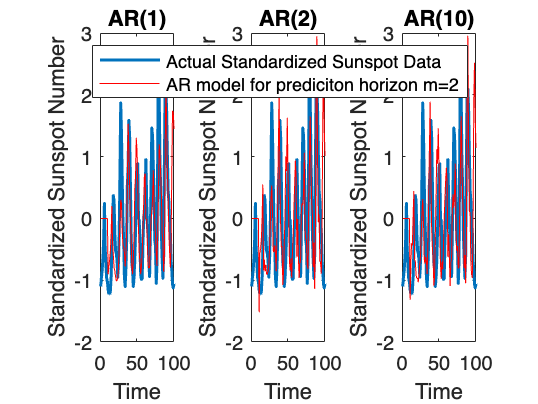

% 2.3.5 - ar modelling sunspot data % change prediction horizon values to
% get graph 

clear all;
load sunspot.dat; % Load sunspot data
sunspot_series = sunspot(:, 2);

% Standardize the data to zero mean and unit variance
sunspot_series_standardized = (sunspot_series - mean(sunspot_series)) / std(sunspot_series);

% Define the prediction horizon
prediction_horizon = 10;

% AR model orders to test
model_orders = [1, 2, 10];

% Number of orders
num_orders = length(model_orders);

% Prepare matrices to store the predicted values
predicted_values_matrix = zeros(length(sunspot_series_standardized), num_orders);

% Loop through the model orders
for i = 1:num_orders
    order = model_orders(i);

    % Calculate AR model coefficients using the aryule function
    [AR_coeffs, ~] = aryule(sunspot_series_standardized, order);

    % Calculate the predictions
    predicted_values = filter(-AR_coeffs(2:end), 1, sunspot_series_standardized);
    predicted_values = [zeros(prediction_horizon, 1); predicted_values(1:end-prediction_horizon)];

    % Store the predicted values in the matrix
    predicted_values_matrix(:, i) = predicted_values;
end

% Plot the actual and predicted values in subplots
figure;
for i = 1:num_orders
    order = model_orders(i);

    subplot(1, num_orders, i);
    plot(sunspot_series_standardized, 'LineWidth', 1.5);
    hold on;
    plot(predicted_values_matrix(:, i), 'r');
    hold off;

    title(sprintf('AR(%d)', order));
    xlabel('Time');
    ylabel('Standardized Sunspot Number');
    xlim([0 100]);   
end
legend('Actual Standardized Sunspot Data','AR model for prediciton horizon m=2')

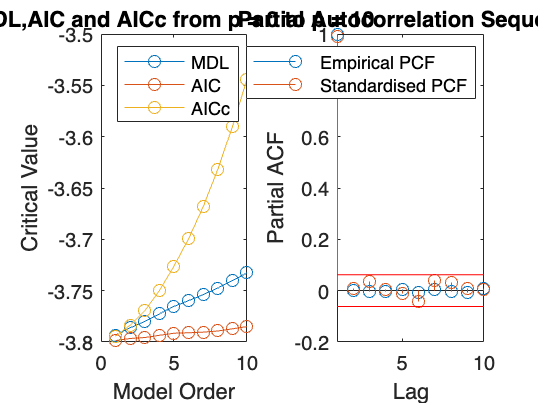

% 2.4.1 
clear all;
load NASDAQ.mat; 
% Standardize the data to zero mean and unit variance
NASDAQ_std = (NASDAQ.Close - mean(NASDAQ.Close)) / std(NASDAQ.Close);


max_p = 10; % Maximum model order
mdl = zeros(max_p, 1);
aic = zeros(max_p, 1);
aicc = zeros(max_p, 1);

for p = 1:max_p
 
    [a, e, k] = aryule(NASDAQ_std, p);
    

    n = length(NASDAQ_std);
    mdl(p) = log(e) + p*log(n)/n;
    aic(p) = log(e) + 2*p/n;
    aicc(p) = aic(p) + (2*p*(p+1))/(n-p-1);
end

figure;
subplot(1,2,1)
plot(1:max_p, mdl, 'o-', 1:max_p, aic, 'o-', 1:max_p, aicc, 'o-');
legend('MDL', 'AIC', 'AICc');
title('MDL,AIC and AICc from p = 0 to p = 10')
xlabel('Model Order');
ylabel('Critical Value');


x = NASDAQ.Close; % Extract data from second column
[arcoefs,E,K] = aryule(x,15);
pacf = -K;
subplot(1,2,2)
stem(pacf)
xlabel('Lag')
ylabel('Partial ACF')
title('Partial Autocorrelation Sequence')
xlim([1 10])
hold on
x_std = (x - mean(x)) / std(x);
[arcoefs,E,K] = aryule(x_std,15);
pacf = -K;
stem(pacf)
xlabel('Lag')
ylabel('Partial ACF')
title('Partial Autocorrelation Sequence')
conf = sqrt(2)*erfinv(0.95)/sqrt(1000);
plot(xlim,[1 1]'*[-conf conf],'r')
hold off
legend(["Empirical PCF","Standardised PCF"])

%%
% 2.5
%loading all csv files 

clear all;
load ECG1_Matteo.csv
load ECG2_Matteo.csv
load ECG3_Matteo.csv


% plotting the whole ECG data
ECG_data= ECG1_Matteo(:, 3);



% splitting the data
unconstrained_breathing = ECG_data(8137:126359);
constrained_50 = ECG_data(130111:251349);
constrained_15 = ECG_data(254857:376555);

fsECG = 500

fsECG = 500

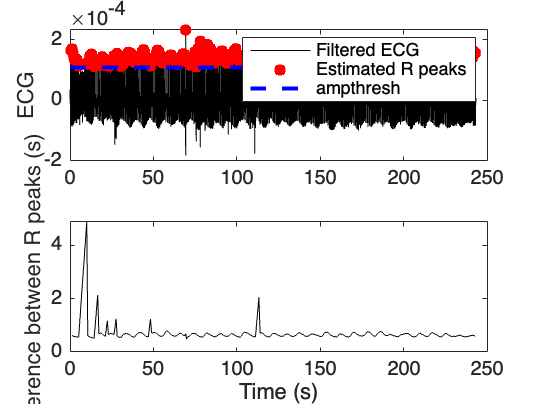

Anomaly corrected.
Anomaly corrected.
Anomaly corrected.
Anomaly corrected.
Anomaly corrected.
Anomaly corrected.
Current plot held


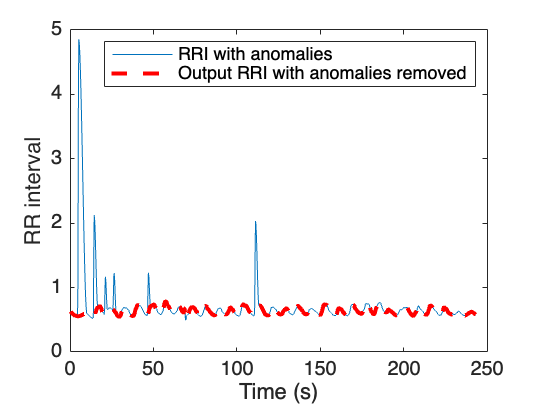

[xRRI,fsRRI]=ECG_to_RRI(constrained_15,fsECG);

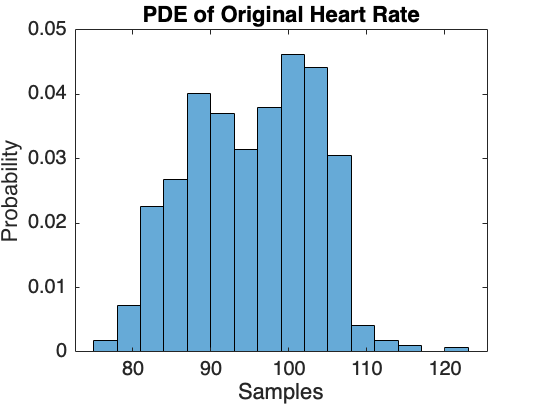

rr_unconstrained = xRRI;
% rr_constrained_50 = xRRI_2;
% rr_constrained_15 = xRRI_3;

h = 60 ./rr_unconstrained ; % calculates heart rate 
figure;
histogram(h, 'Normalization','pdf');
title('PDE of Original Heart Rate');
ylabel('Probability');
xlabel('Samples');

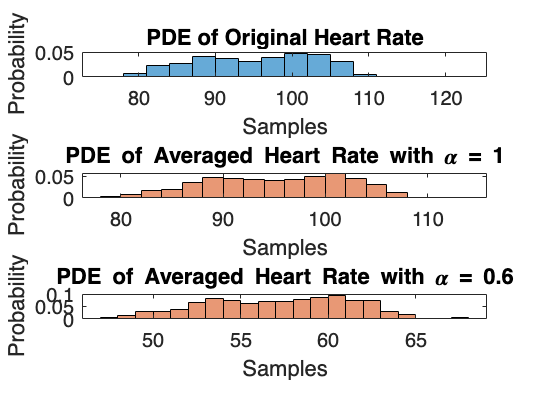


% Calculate the averaged heart rates with different alpha values
alpha1 = 1;
alpha2 = 0.6;
n = 10;

h_avg1 = average_hr(h, n, alpha1);
h_avg2 = average_hr(h, n, alpha2);


figure;
subplot(3,1,1);
histogram(h, 'Normalization', 'pdf');
title('PDE of Original Heart Rate');
ylabel('Probability');
xlabel('Samples');

subplot(3,1,2);
histogram(h_avg1, 'Normalization', 'pdf','FaceColor',"#D95319");
title('PDE of Averaged Heart Rate with \alpha = 1');
ylabel('Probability');
xlabel('Samples');

subplot(3,1,3);
histogram(h_avg2, 'Normalization', 'pdf','FaceColor',"#D95319");
title('PDE of Averaged Heart Rate with \alpha = 0.6');
ylabel('Probability');
xlabel('Samples');

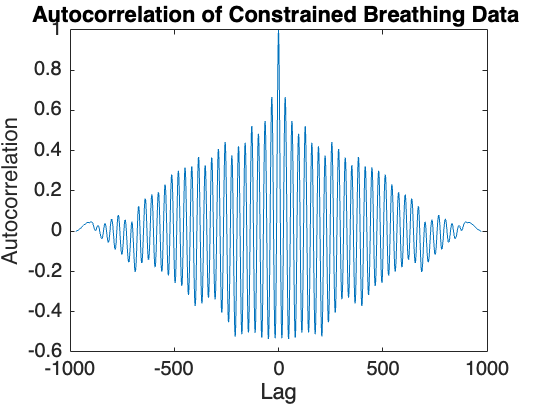

% autocorrelation of RRI data 
rr_unconstrained_detrend = detrend(rr_unconstrained);
% rr_constrained_50_detrend = detrend(rr_constrained_50);
% rr_constrained_15_detrend = detrend(rr_constrained_15);
[autocorr_rr_unconstrained_detrend , lags1] = xcorr(rr_unconstrained_detrend, 'coeff');
figure;
plot(lags1, autocorr_rr_unconstrained_detrend);
title('Autocorrelation of Constrained Breathing Data ');
xlabel('Lag');
ylabel('Autocorrelation');

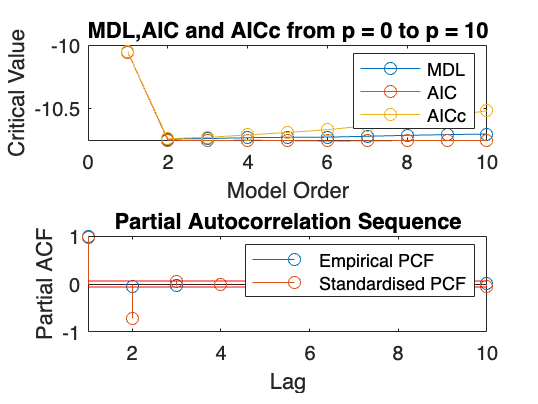

% finding ar model of heart rate trials 

max_p = 10; 
mdl = zeros(max_p, 1);
aic = zeros(max_p, 1);
aicc = zeros(max_p, 1);

for p = 1:max_p
    
    [a, e, k] = aryule(rr_unconstrained_detrend, p);
    
    
    n = length(rr_unconstrained_detrend);
    mdl(p) = log(e) + p*log(n)/n;
    aic(p) = log(e) + 2*p/n;
    aicc(p) = aic(p) + (2*p*(p+1))/(n-p-1);
end


figure;
subplot(2,1,1)
plot(1:max_p, mdl, 'o-', 1:max_p, aic, 'o-', 1:max_p, aicc, 'o-');
legend('MDL', 'AIC', 'AICc');
title('MDL,AIC and AICc from p = 0 to p = 10')
xlabel('Model Order');
ylabel('Critical Value');


x= rr_unconstrained;
[arcoefs,E,K] = aryule(x,10);
pacf = -K;
subplot(2,1,2)
stem(pacf)
xlabel('Lag')
ylabel('Partial ACF')
title('Partial Autocorrelation Sequence')
xlim([1 10])
hold on
x_std = rr_unconstrained_detrend;
[arcoefs,E,K] = aryule(x_std,10);
pacf = -K;
stem(pacf)
xlabel('Lag')
ylabel('Partial ACF')
title('Partial Autocorrelation Sequence')
conf = sqrt(2)*erfinv(0.95)/sqrt(1000);
plot(xlim,[1 1]'*[-conf conf],'r')
hold off
legend(["Empirical PCF","Standardised PCF"])

% ASSIGNMENT 3 - 3.5 - RELATED TO RRI
data_length = rr_unconstrained_detrend;

[Pxx_std, F_std] = periodogram(rr_unconstrained_detrend);
F_norm = F_std / (10/2);
figure;
subplot(3,1,1)
plot(F_norm, Pxx_std);
xlabel('Normalized Frequency');
ylabel('PSD');
title('Periodogram of RRI data (Constrained Breathing at 15 bpm)');
xlim([0 0.5])
sample_one = 63

sample_one = 63

[pxx,f] = pwelch(rr_unconstrained_detrend,63,[],[],[]);
% [Pxx_welch, F_welch] = pwelch(rr_unconstrained_detrend, sample_one);
subplot(3,1,2)
plot(f, pxx);
xlabel('Normalized Frequency');
ylabel('PSD');
title('Averaged Periodogram of RRI data (Constrained Breathing at 15 bpm) - 63s Window Length');
xlim([0 0.5])
sample_two = 189

sample_two = 189

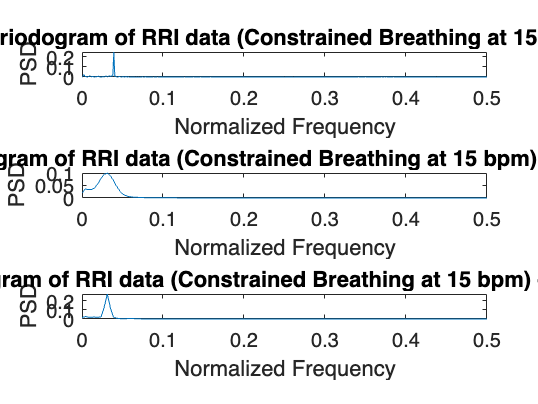

[pxx,f] = pwelch(rr_unconstrained_detrend,189,[],[],[]);
subplot(3,1,3)
plot(f, pxx);
xlabel('Normalized Frequency');
ylabel('PSD');
title('Averaged Periodogram of RRI data (Constrained Breathing at 15 bpm) - 189s Window Length');
xlim([0 0.5])

function avg_h = average_hr(h, n, alpha)
    avg_h = zeros(length(h) - n + 1, 1);
    for i = 1:(length(h) - n + 1)
        avg_h(i) = (1/n) * alpha * sum(h(i:(i+n-1)));
    end
end


function [PbX, freq] = pgm_norm(x)
% Calculates the periodogram of a sequence x using the given equation
% with a normalized frequency axis going from 0 to 1
%   PbX: the periodogram of x, a sequence of length N
%   freq: the normalized frequency axis, a sequence of length N

N = length(x);
PbX = zeros(N, 1);
freq = (0:N-1)/N; % normalized frequency axis
for f = 1:N
    for n = 1:N
        PbX(f) = PbX(f) + x(n) * exp(-1i*2*pi*(f-1)*(n-1)/N);
    end
    PbX(f) = abs(PbX(f))^2 / N;
end
end 








